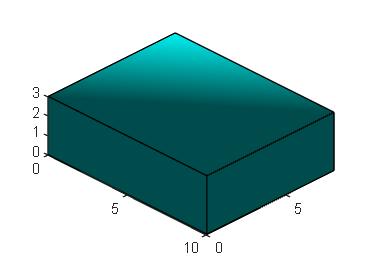

Error using patch
Invalid color name or hexadecimal color code. Valid names include: 'red', 'green', 'blue', 'cyan', 'magenta', 'yellow', 'black', 'white', and 'none'. Valid hexadecimal color codes consist of '#' followed by three or six hexadecimal digits.

% Create a figure
fig = figure;

% Create axes for 3D plotting
ax = axes('Parent', fig);

% Load the floor texture image
floorTexture = imread('roomwall.jpeg');

% Load the wall texture image
wallTexture = imread('roomwall.jpeg');

% Get the size of the wall texture image
wallSize = size(wallTexture);

% Get the size of the floor texture image
imageSize = size(floorTexture);

% Define room dimensions
roomLength = 10;
roomWidth = 8;
roomHeight = 3;

% Define room corners
corners = [
    0, 0, 0;
    roomLength, 0, 0;
    roomLength, roomWidth, 0;
    0, roomWidth, 0;
    0, 0, roomHeight;
    roomLength, 0, roomHeight;
    roomLength, roomWidth, roomHeight;
    0, roomWidth, roomHeight
];

% Draw room using patch
room = patch('Vertices', corners, 'Faces', [1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8; 1 2 3 4; 5 6 7 8], 'FaceColor', 'cyan', 'EdgeColor', 'k');

% Set axis limits
axis(ax, 'equal');
axis(ax, [0 roomLength 0 roomWidth 0 roomHeight]);

% Set view to first-person perspective
view(ax, 45, 30);

% Add camera toolbar for interactive control
cameratoolbar('SetMode', 'orbit');

% Customize lighting and appearance as needed
% Add lighting to the room
light('Position', [roomLength/2, roomWidth/2, roomHeight], 'Style', 'local');

% Set lighting properties
lighting(ax, 'phong');
material(ax, 'dull');

% Compute the coordinates for the floor texture
xDataFloor = linspace(0, roomLength, imageSize(2));
yDataFloor = linspace(0, roomWidth, imageSize(1));

% Display the floor texture as the background
image('XData', xDataFloor, 'YData', yDataFloor, 'CData', floorTexture, 'Parent', ax, 'CDataMapping', 'scaled');

% Compute the coordinates for the wall texture
xDataWall = linspace(0, roomLength, wallSize(2));
yDataWall = linspace(0, roomHeight, wallSize(1));

% Draw walls using patch
walls = patch('Vertices', [corners(1:4, :); repmat([0, 0, roomHeight], 4, 1)], ...
    'Faces', [1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8; 1 2 3 4], 'FaceColor', 'texture', 'EdgeColor', 'none', ...
    'CData', wallTexture, 'FaceAlpha', 1);


% Adjust figure settings
set(fig, 'Name', 'Matlab Living Room', 'NumberTitle', 'off');
